# 2223-MA378 : Lab 1 (Solutions)

Lab 1 of Numerical Analysis 2: Experiments with polynomial interpolation 

- **Name: Niall Madden **[Change this to your name before submitting!!!!] 

- ID: `01234567` [Change this to your ID]

- Email:  `n.madden321@universityofgalway.ie` [*Change this to your email address*]

- Jan 2023

- Upload your script with solutions to Exercises 1, 2, 3 and 4 to Blackboard (2223-MA378... Labs ... Lab 1). 

## Defining the function that we will interpolate

In MATLAB, we can define functions using the "@" symbol. The syntax is:

Here the expession can be anything, but usually involves 

- the standard arithmetic operators: `+`, `-`, `*` and `/.` However, we will often write "`.*`" and "`./`" for multiplication and devision so that these are done "entrywise" for vectors.

- standard mathematics functions, such as l`og()`, `exp()`, `sin()`, `cos()`, `abs()`, etc.

In this first example, we will define $f(x)= e^{\cos(x/2)}$.

f = @(x)(exp(cos(x/2)));

Let's plot this on the interval $[-5,5]$.

figure(1);
fplot(f,[-5,5]);
title('Plot of exp(cos(x/2)');

## Computing the interpolant

We could compute the interpolant to this function using Lagrange Interpolation. But MATLAB  has built-in functions for this, which we want to use.

The two main functions we use are:

- `polyfit(x,y,n)` which returns the coefficients of the polynomial of degree $n$ that inpterpolates the points. If we set `C = polyfit(x,y,n)` then `C` is a vector with $n+1$ entries. `C(1)` is the coeficient of $x^n$, `C(2)` is the coefficient of $x^{n-1}$, etc. However, we usually just want to compute C, and don't really care what the acual coefficents are.

- `polyval(C,X) `evaluates the polynomial represented by $C$. `Y = polyval(C,X)` would set $Y(i)$ to be the value of the polynomial at $X(i)$.

To compute the interpolant, we need to choose the end points $a$ and $b$:

a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].

Next, we choose $n$, the degree of the interpolating polynomial. Note that we'll have $n+1$ interpolation points.

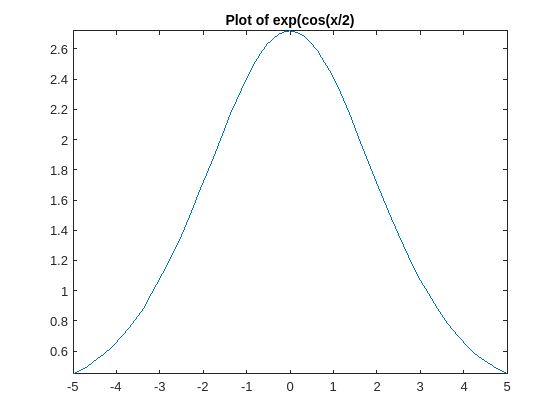

n = 2;    % degree of the interpolation polynomial.

Next define the interpolation points:

x = linspace(a, b, n+1)  % the points x(1), x(2), ..., x(n+1)

Finally, define the vector of values to be interpolated.

y = f(x);   % the points to interpolate

Now that we have the data, we can actually do the interpolation

C = polyfit(x,y,n); % C is a vector containing the coefs of

x =     -5     0     5


                    % of the polynomial interpolant of f(x)

## Plotting the function and the interpolation

We'll define $X$ to be a vector of 1000 points between $a$ and $b$. This is just to help with plotting.

X = linspace(a, b, 100);   % X is a collection of 1000 in [a,b]

Finally we plot:

plot(x,y, 'o',...
   X, f(X), ...
   X, polyval(C,X), '--', ...
   'LineWidth',3, 'MarkerSize', 10)
legend('points', 'f', 'p_n');
title('f(x) and p_n(x)');

## Calculating and plotting the error

The Error at a given $x$ is $E(x) = |f(x)-p_n(x)|$. We'll define the vector of errors:

E = abs(f(X)-polyval(C,X));

The maximum value is:

disp(max(E))

We can also plot it:

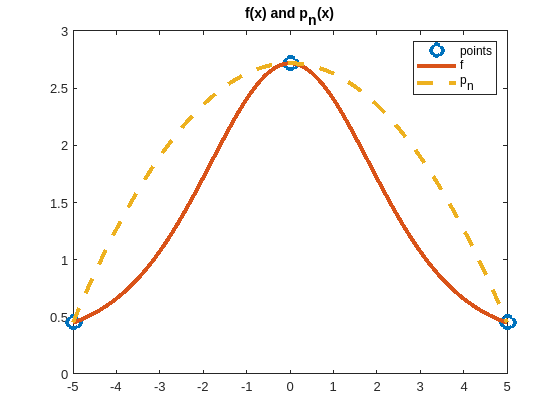

plot( X, E, '--')

title('Error: f(x)-p_n(x)');

## Exercise 1

Change the data at the top of this sheet to your name, ID, and email address. You are welcome to collaborate with classmates on this work. No need to include their data, however.

## Exercise 2

Copy the code for 

- defining $f$, $a$, $b$, $n$, $x$, and $y$ 

- interpolating $f(x)=e^\cos(x/2)$; that is computing $C$. 

- and for computing the maximum error; that is - compute $E$ and display its maximum value.

to here. **Then experiement to find the smallest value of **$n$** for which **$\max_{-5 \leq x \leq 5} f(x)-p_n(x) \leq 10^{-3}$. Ignore any warnings about the polynomial being "badly conditioned". Generally, you should note that, as $n$ increases, the maximum error decreases.

### Solution:

f = @(x)(exp(cos(x/2)));
a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].
n = 18; % with n=18, we get an error less than 1e-3

    0.8281



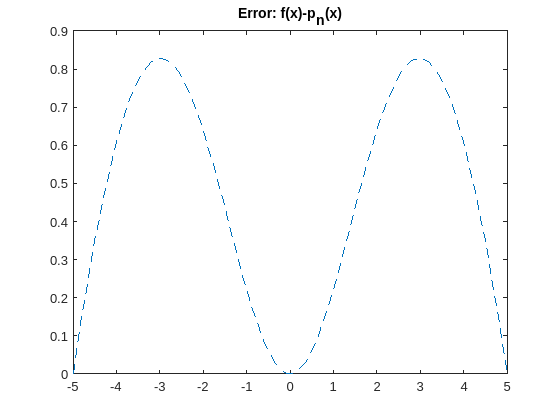

x = linspace(a, b, n+1);
y = f(x);   % the points to interpolate
C = polyfit(x,y,n); 

E = abs(f(X)-polyval(C,X));
disp(max(E))

## Exercise 3

Exercise 2 (and the Weierstrass Interpolation theorem which I'll tell you about in class) might suggest that, for any $f$, we can make the error as small as we want by taking $n$ big enough. However, that is not true, at least if equally spaced points are used. 

To see this, change the definition of the function to $f(x) = \frac{1}{1+x^2}$. In MATLAB this is:

Demonstrate that, as $n$ increases, so too does the error. For example, determine the smallest value of $n$ for which the error is **greater** than 1. How about greater than 10? Or 100? or 1,000?

### Solution

Note: I don't expect students to do a for loop.

f = @(x)(1./(1+x.^2));
a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].

for n = 2:20 % with n=18, we get an error less than 1e-3
   x = linspace(a, b, n+1);
   y = f(x);   % the points to interpolate
   C = polyfit(x,y,n);
   E = abs(f(X)-polyval(C,X));

   7.5968e-04



   disp([n, max(E)])
end

## Exercise 4

Instead of using equally spaced points, try choosing the points by hand. Start with $x_0=-5$, $x_1=0$, and $x_2=5$. Now choose $x_3$

and $x_4$ in a way that you think will reduce the error. And then $x_5$ and $x_6$ and so on. Using about 20 points you should be able to get the error close to $10^{-2}$.

*Tip: *Since the function is symmetric about $x=0$, just define, say, the points on $[-5,0]$ and then extend to $[-5,5]$ as follows:

*Another tip: *In previous exercises, we would choose $n$, and that would determine the values for $x$. In this Exercise, we are choosing the points in $x$, which determines the degree of the polynomial. So, after defining $x$, you need to set the value of $n$. That can be done as follows:

### Solution

f = @(x)(1./(1+x.^2));
a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].
x = [-5, 0, -2.1, -4.1,-4.697, -3.18,  -1];
x = union(x,-x)
n = length(x)-1
y = f(x);   % the points to interpolate
C = polyfit(x,y,n);
E = abs(f(X)-polyval(C,X));
plot(X, f(X), X, polyval(C,X), x, f(x), 'o')
plot(X, E, '--o')

    2.0000    0.6460

    3.0000    0.7045

    4.0000    0.4383

    5.0000    0.4303

    6.0000    0.6164

    7.0000    0.2453

    8.0000    1.0451

    9.0000    0.2980

   10.0000    1.9154

   11.0000    0.5539

   12.0000    3.6117

   13.0000    1.0645

   14.0000    7.1893

   15.0000    2.0967

   16.0000   14.0135

   17.0000    4.0493

   18.0000   27.5068



   19.0000    8.1907



   20.0000   58.4067



## Bonus Exercise

You don't have to submit a solution to this part. But if you have time, please try it out.  

Although we won't cover it in class, Chebyshev showed that, in general, one should choose points given by the formula: $ x_i = \frac{b-a}{2}\cos\bigg( \frac{(i + \frac{1}{2})\pi}{n+1}\bigg) + \frac{b+a}{2}, \qquad \text{ for } \quad i=0, 1, \dots, n.$

Try this for various $n$ and test if it works. If you are interested, see Sections 8.4 and 8.5 of Suli and Mayers' "An Introduction to Numerical Analysis". Try this by writing some code which computes the interpolant for a given $n$ on the points obtained by the formula above. As $n$ increases, you should observe that the error decreases.

### Solution

f = @(x)(1./(1+x.^2));
a = -5; b = 5; % Approximate f(x) in the interval [a,b]=[-5,5].

n = 20;

x =    -5.0000   -4.6970   -4.1000   -3.1800   -2.1000   -1.0000         0    1.0000    2.1000    3.1800    4.1000    4.6970    5.0000


i = 0:n;

n = 12

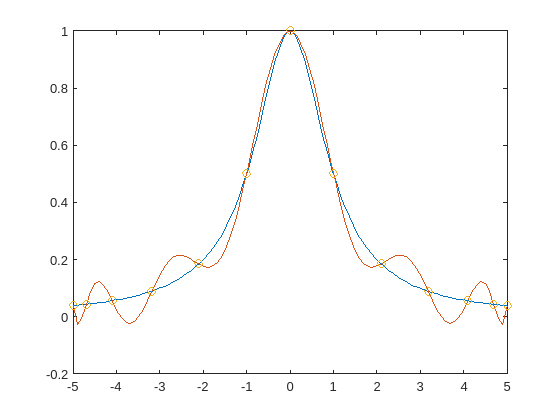

x = (b-a)/2*cos( (i+1/2)*pi/(n+1)) + (b+a)/2;
y = f(x);   % the points to interpolate
C = polyfit(x,y, n);
E = abs(f(X)-polyval(C,X));

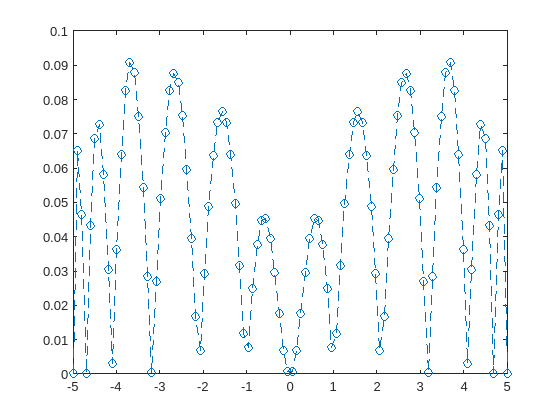

disp([n, max(E)])

   20.0000    0.0150



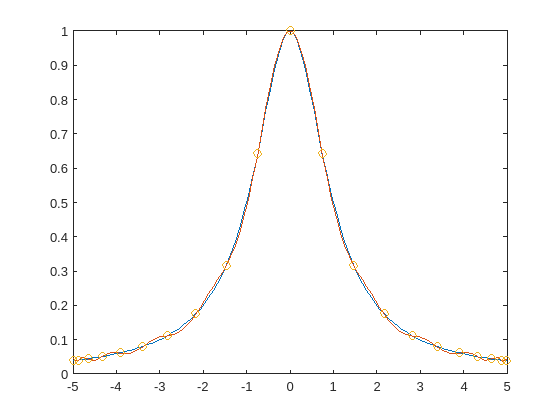

plot(X, f(X), X, polyval(C,X), x, f(x), 'o')